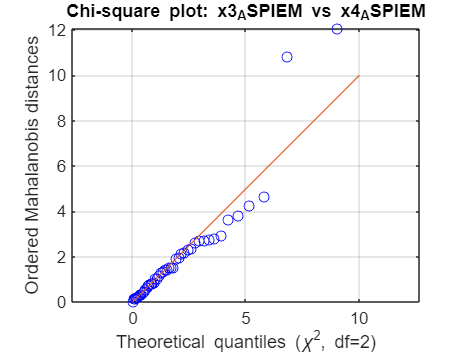

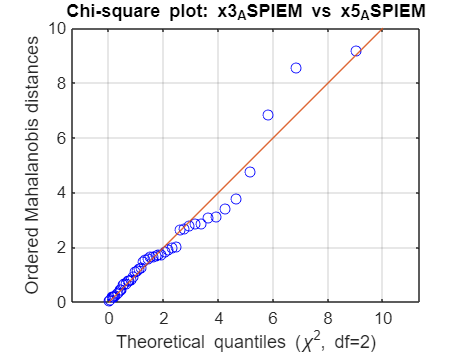

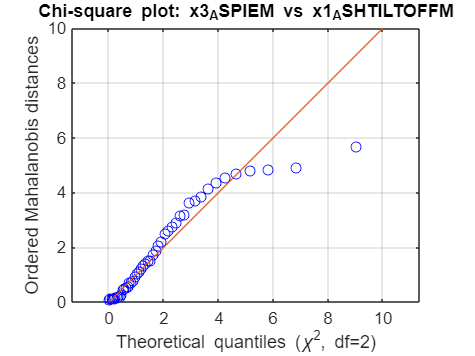

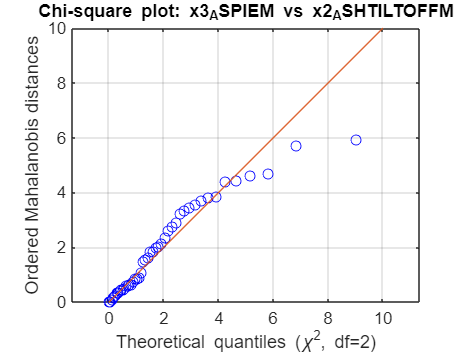

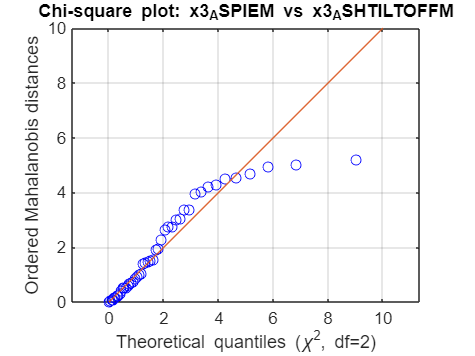

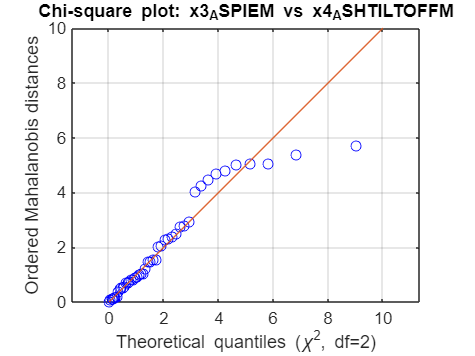

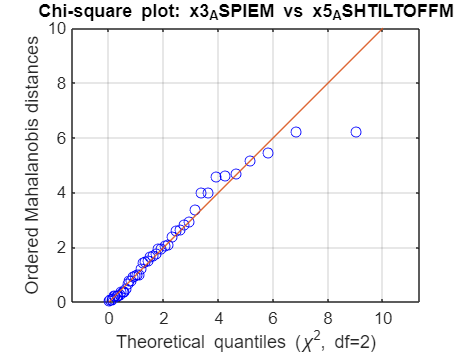

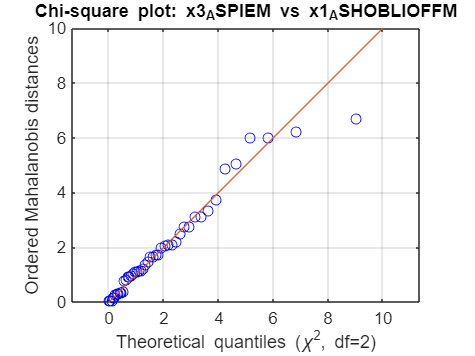

clc; clear; close all;


% -----------------------------
% Cargar datos como tabla
% -----------------------------
filename = 'Five_times_Kinematics_HT_Query_MATLAB_SIN_OUTLIERS.xlsx';
numericData = readtable(filename);

X = numericData{:,:};      % Solo datos numéricos
[n, p] = size(X);

% Parámetros de bootstrap
B = 500;                   % número de réplicas
alpha = 0.05;              % nivel de significancia
lower_p = alpha/2;
upper_p = 1 - alpha/2;

% -----------------------------
% Chi-square plots bivariados
% Comparar variable 3 con todas las siguientes (desde la 4)
% -----------------------------
dim_interes = 65;

for j = 66:p
    % Extraer submatriz bivariada
    X_sub = [X(:, dim_interes), X(:, j)];  % n x 2

    % Estadísticos de ajuste
    mean_vec = mean(X_sub);
    cov_mat   = cov(X_sub);
    inv_cov   = pinv(cov_mat);

    % Distancias de Mahalanobis observadas
    D2_obs = zeros(n,1);
    for i = 1:n
        d = X_sub(i,:) - mean_vec;
        D2_obs(i) = d * inv_cov * d';
    end
    D2_obs_sorted = sort(D2_obs);

    % Cuantiles teóricos chi² (df = 2)
    chi2_q = chi2inv(((1:n)' - 0.5) / n, 2);

    % -----------------------------
    % Bootstrap paramétrico para la banda
    % -----------------------------
    D2_boot = zeros(n, B);
    for b = 1:B
        % Simular n observaciones MVN
        Xb = mvnrnd(mean_vec, cov_mat, n);
        % Calcular distancias y ordenar
        db_mat = Xb - mean_vec;  % n x 2
        D2b = sum((db_mat * inv_cov) .* db_mat, 2);  % n x 1
        D2_boot(:,b) = sort(D2b);
    end

    % Calcular percentiles fila a fila
    lower_env = quantile(D2_boot, lower_p, 2);
    upper_env = quantile(D2_boot, upper_p, 2);

    % -----------------------------
    % Gráfico con banda de confianza
    % -----------------------------
    varName_i = numericData.Properties.VariableNames{dim_interes};
    varName_j = numericData.Properties.VariableNames{j};

    figure;
    hold on;
    % Banda gris
    fill( [chi2_q; flipud(chi2_q)], ...
          [lower_env; flipud(upper_env)], ...
          [0.9 0.9 0.9], 'EdgeColor','none');
    % Línea identidad
    plot(chi2_q, chi2_q, 'r--', 'LineWidth',1.2);
    % Datos observados
    plot(chi2_q, D2_obs_sorted, 'bo', 'MarkerFaceColor','b');
    hold off;

    axis equal; grid on;
    xlabel('\chi^2 teóricos (df = 2)');
    ylabel('Distancias de Mahalanobis ordenadas');
    title(sprintf('Chi-square plot: %s vs %s', varName_i, varName_j));
    legend('Banda 95%','y = x','Datos', 'Location','best');
end


